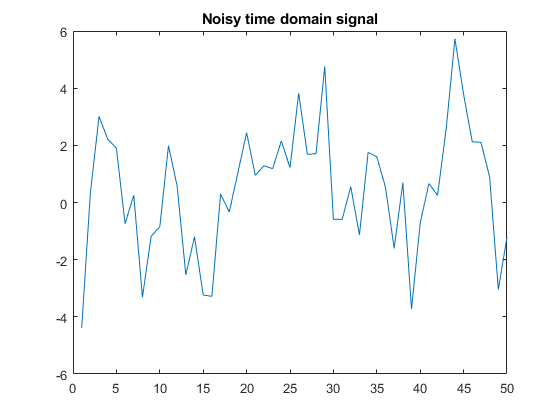

t = 0:.001:.25;
x = sin(2*pi*50*t) + sin(2*pi*120*t);
y = x + 2*randn(size(t));
plot(y(1:50))
title('Noisy time domain signal')

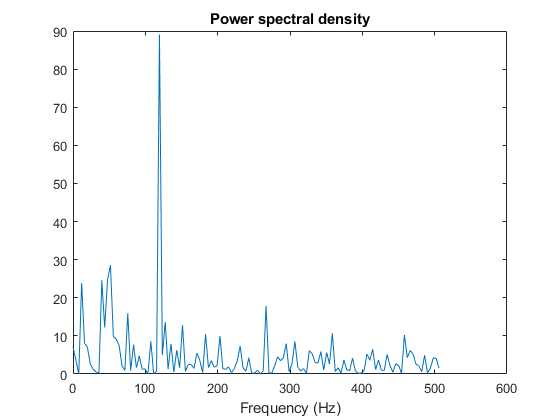

Y = fft(y,251);
Pyy = Y.*conj(Y)/251;
f = 1000/251*(0:127);
plot(f,Pyy(1:128))
title('Power spectral density')
xlabel('Frequency (Hz)')

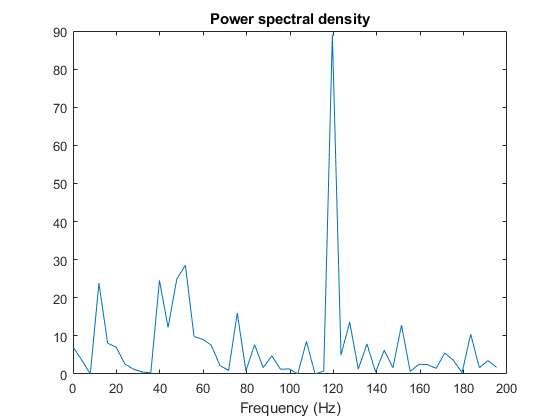

plot(f(1:50),Pyy(1:50))
title('Power spectral density')
xlabel('Frequency (Hz)')

[y, fs] = audioread("C:\Users\TC\Desktop\a4.wav");

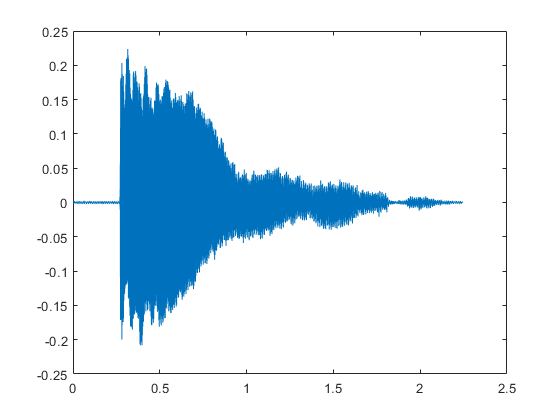

t = 1/fs:20/fs:size(y, 1)/fs;
plot(t, y(1:20:size(y, 1)))

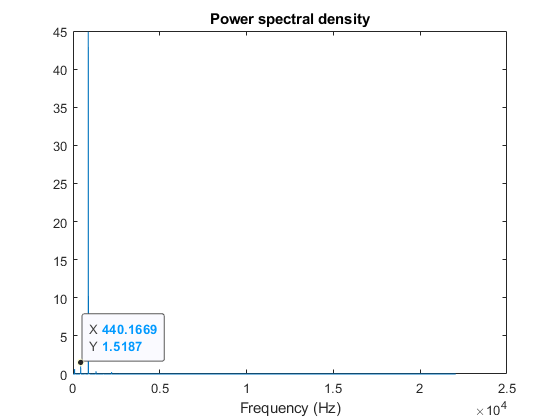

Y = fft(y, 98987);
Pyy = Y.*conj(Y)/98987;
f = fs/98987*(0:49493);
plot(f,Pyy(1:49494))
title('Power spectral density')
xlabel('Frequency (Hz)')